t_1 = 1; t_2 = 6; a = 5;

T = 100; dt = 0.01; %период и частота дискретизации
t=-T/2:dt:T/2; % Вектор времени
V = 1/dt; % Ширина диапазона частот
dv = 1/T; % Шаг частоты
v = -V/2 : dv : V/2; % Набор частот для FFT

g = zeros(1,length(t)); %задаем массив функции
for i = 1:length(t)
    if (t_1 <= t(i)) && (t(i) <= t_2) 
        g(1,i) = a;
    else 
        g(1,i) = 0;
    end
end

%ФНЧ (Убираем высокие частоты)
% b = 0.3; c = 0; d = 2;
% u = g + b*(rand(size(t))-0.5) + c*sin(d*t); %шум
% 
% v_0 = 1;
% U = fftshift(fft(u)); %образ зашумленного
% F=1.*(-v_0<=v & v<=v_0); %фильтр
% U_filt = F.*U; %обрезанный образ
% u_filt = ifft(ifftshift(U_filt)); %обработанный сигнал
% 
% f1 = figure; %частотная плоскость (образы)
% hold on
% p1 = plot(v, abs(U)); %модуль образа зашумленной
% p2 = plot(v, abs(U_filt)); %модуль образа обрезанной
% p1.LineWidth = 1.5;
% p2.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([0 8])
% ylim([0 2500])
% legend('U(\nu)', 'U_{filt}(\nu)')
% set(gca, 'XTick', 0:1:10)
% hold off
% text(3.5,1700,sprintf('v_0 = %1.1f,   b = %1.1f', v_0, b), 'Color','red','FontSize',10)
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_3\2_4.png');
% 
% f2 = figure; %временная плосксоть (праобразы)
% hold on
% p3 = plot(t,g); %исходный зашумленный сигнал
% p4 = plot(t, u_filt); %обработанный сигнал
% p3.LineWidth = 1.5;
% p4.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([0 10])
% legend('u(t)', 'u_{filt}(t)')
% set(gca, 'XTick', 0:1:10)
% hold off
% text(7,4,sprintf('v_0 = %1.1f,   b = %1.1f', v_0, b), 'Color','red','FontSize',10)
% saveas(f2,'C:\LATEX\Fourier_analiz\Fourier_3\1_4.png');

% f3 = figure; %временная плосксоть (праобразы)
% plot(t,u) %исходный зашумленный сигнал
% grid on
% xlabel("t")
% xlim([0 7])
% legend('u(t)')
% set(gca, 'XTick', 0:1:10, 'YTick', -1:1:10)
% saveas(f3,'C:\LATEX\Fourier_analiz\Fourier_3\2_noise.png');

% %Убираем специфические частоты
% b = 0; c = 3; d = 5;
% u = g + b*(rand(size(t))-0.5) + c*sin(d*t); %шум
% v_0 = d/(2*pi);
% 
% U = fftshift(fft(u)); %образ зашумленного
% F=1.*((v>=-(v_0-0.05) & v<=v_0-0.05) | (v>=v_0+0.05 & v<=v_0+1) | (v>=-(v_0+1) & v<=-(v_0+0.05))); %фильтр
% U_filt = F.*U; %обрезанный образ
% u_filt = ifft(ifftshift(U_filt)); %обработанный сигнал
% 
% f1 = figure; %частотная плоскость (образы)
% hold on
% p1 = plot(v, abs(U)); %модуль образа зашумленной
% p2 = plot(v, abs(U_filt)); %модуль образа обрезанной
% p1.LineWidth = 1.5;
% p2.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([0 2])
% legend('U(\nu)', 'U_{filt}(\nu)')
% set(gca, 'XTick', 0:0.1:2)
% hold off
% text(1.3,3000,sprintf('b = %1.1f, c = %1.1f, d = %1.1f', b, c, d), 'Color','red','FontSize',10)
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_3\4_4.png');

% f2 = figure; %временная плосксоть (праобразы)
% hold on
% p3 = plot(t,g); %исходный зашумленный сигнал
% p4 = plot(t, u_filt); %обработанный сигнал
% p3.LineWidth = 1.5;
% p4.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([0 7])
% legend('u(t)', 'u_{filt}(t)')
% set(gca, 'XTick', 0:1:10)
% hold off
% text(2,1,sprintf('b = %1.1f, c = %1.1f, d = %1.1f', b, c, d), 'Color','red','FontSize',10)
% saveas(f2,'C:\LATEX\Fourier_analiz\Fourier_3\3_4.png');

% f3 = figure; %временная плосксоть (праобразы)
% plot(t,u) %исходный зашумленный сигнал
% grid on
% xlabel("t")
% xlim([0 7])
% legend('u(t)')
% set(gca, 'XTick', 0:1:10, 'YTick', -1:1:10)
% saveas(f3,'C:\LATEX\Fourier_analiz\Fourier_3\3_noise.png');

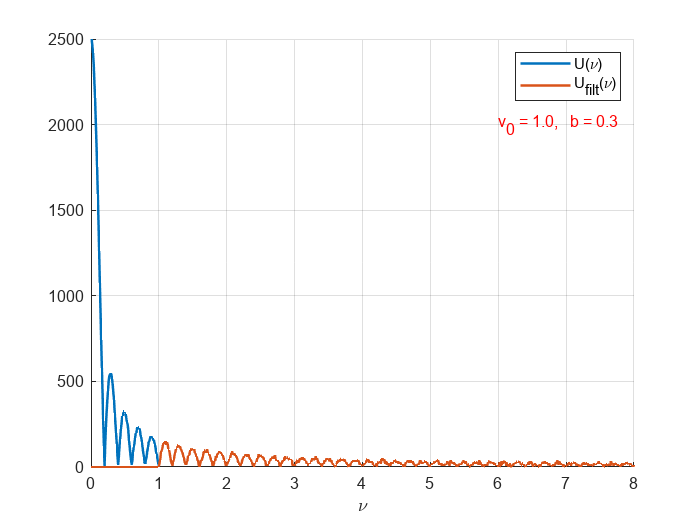

%ФВЧ (Убираем низкие частоты)
b = 0.3; c = 0; d = 2;
u = g + b*(rand(size(t))-0.5) + c*sin(d*t); %шум

v_0 = 1;
U = fftshift(fft(u)); %образ зашумленного
F=0.*(-v_0<v & v<v_0)+1.*(v<=-v_0 | v>=v_0); %фильтр
U_filt = F.*U; %обрезанный образ
u_filt = ifft(ifftshift(U_filt)); %обработанный сигнал

f1 = figure; %частотная плоскость (образы)
hold on
p1 = plot(v, abs(U)); %модуль образа зашумленной
p2 = plot(v, abs(U_filt)); %модуль образа обрезанной
p1.LineWidth = 1.5;
p2.LineWidth = 1.5;
grid on
xlabel("\nu")
xlim([0 8])
ylim([0 2500])
legend('U(\nu)', 'U_{filt}(\nu)')
set(gca, 'XTick', 0:1:10)
hold off
text(6,2000,sprintf('v_0 = %1.1f,   b = %1.1f', v_0, b), 'Color','red','FontSize',10)
saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_3\6_4.png');

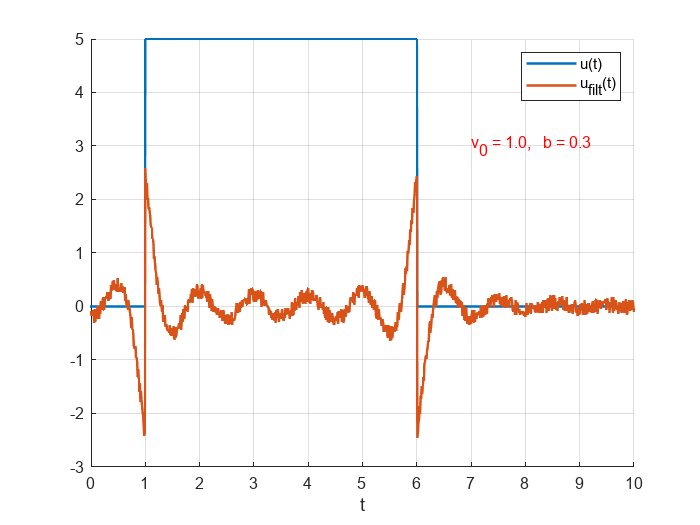


f2 = figure; %временная плосксоть (праобразы)
hold on
p3 = plot(t,g); %исходный зашумленный сигнал
p4 = plot(t, u_filt); %обработанный сигнал
p3.LineWidth = 1.5;
p4.LineWidth = 1.5;
grid on
xlabel("t")
xlim([0 10])
legend('u(t)', 'u_{filt}(t)')
set(gca, 'XTick', 0:1:10)
hold off
text(7,3,sprintf('v_0 = %1.1f,   b = %1.1f', v_0, b), 'Color','red','FontSize',10)
saveas(f2,'C:\LATEX\Fourier_analiz\Fourier_3\5_4.png');


% f3 = figure; %временная плосксоть (праобразы)
% plot(t,u) %исходный зашумленный сигнал
% grid on
% xlabel("t")
% xlim([0 7])
% legend('u(t)')
% set(gca, 'XTick', 0:1:10, 'YTick', -1:1:10)
% saveas(f3,'C:\LATEX\Fourier_analiz\Fourier_3\4_noise.png');